imagedir = "simplearmory_images";

images = load_images(imagedir);

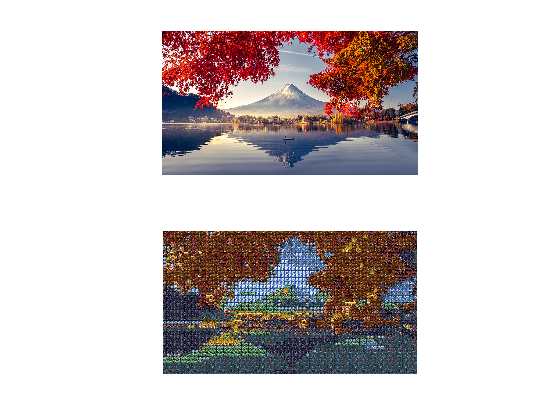

k = 50;
tile_size = 36;

image_folder = 'Test_Images';
image_filename = 'test5.jpg';  
image_path = fullfile(image_folder, image_filename);
base_image = im2double(imread(image_path));

for i = 1:numel(images)
    images{i} = imresize(images{i}, [tile_size, tile_size]);
end

opt_images = optimize_images(images, k);
%opt_images = optimize_images2(base_image, images, k);


desired_base_size = [1440 2560]; 
base_image = imresize(base_image, desired_base_size);

reconstructed_image = reconstruct_image(base_image, opt_images, tile_size);
figure;
subplot(2, 1, 1);
imshow(base_image);
subplot(2, 1, 2);
imshow(reconstructed_image);

sampDegree = visualAngle(512,20,-1,1);
whitePoint = [95.05,100,108.9];

xyzConst = rgb2xyz(reconstructed_image);
xyxOriginal = rgb2xyz(base_image);

S_CIELAB = scielab(sampDegree,xyxOriginal,xyzConst,whitePoint,'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...



mean(mean(S_CIELAB))

ans = 1.5014